# HH Model 方程及参数

% Parameters (from original Hodgkin-Huxley paper)
Cm = 1.0; % Membrane capacitance (uF/cm^2)
gK = 36.0; % Max potassium conductance (mS/cm^2)
gNa = 120.0; % Max sodium conductance (mS/cm^2)
gL = 0.3; % Leak conductance (mS/cm^2)
VK = -12.0; % Potassium reversal potential (mV)
VNa = 115.0; % Sodium reversal potential (mV)
VL = 10.613; % Leak reversal potential (mV)

% Define the Hodgkin-Huxley ODE system
function dydt = hodgkin_huxley(~, y, I, Cm, gK, gNa, gL, VK, VNa, VL)
    V = y(1);
    n = y(2);
    m = y(3);
    h = y(4);
    
    % Compute gating variable rates
    an = alpha_n(V);
    bn = beta_n(V);
    am = alpha_m(V);
    bm = beta_m(V);
    ah = alpha_h(V);
    bh = beta_h(V);
    
    % Ionic currents
    IK = gK * n^4 * (V - VK); % Potassium current
    INa = gNa * m^3 * h * (V - VNa); % Sodium current
    IL = gL * (V - VL); % Leak current
    
    % Membrane potential dynamics
    dVdt = (I - (IK + INa + IL)) / Cm;
    
    % Gating variable dynamics
    dndt = an * (1 - n) - bn * n;
    dmdt = am * (1 - m) - bm * m;
    dhdt = ah * (1 - h) - bh * h;
    
    % Return derivatives
    dydt = [dVdt; dndt; dmdt; dhdt];
end

% Define rate functions for gating variables
function a = alpha_n(V)
    if V == 10
        a = 0.1; % Avoid division by zero
    else
        a = 0.01 * (10 - V) / (exp((10 - V) / 10) - 1);
    end
end

function b = beta_n(V)
    b = 0.125 * exp(-V / 80);
end

function a = alpha_m(V)
    if V == 25
        a = 1; % Avoid division by zero
    else
        a = 0.1 * (25 - V) / (exp((25 - V) / 10) - 1);
    end
end

function b = beta_m(V)
    b = 4 * exp(-V / 18);
end

function a = alpha_h(V)
    a = 0.07 * exp(-V / 20);
end

function b = beta_h(V)
    b = 1 / (exp((30 - V) / 10) + 1);
end

# 可调初始值、时间；绘图

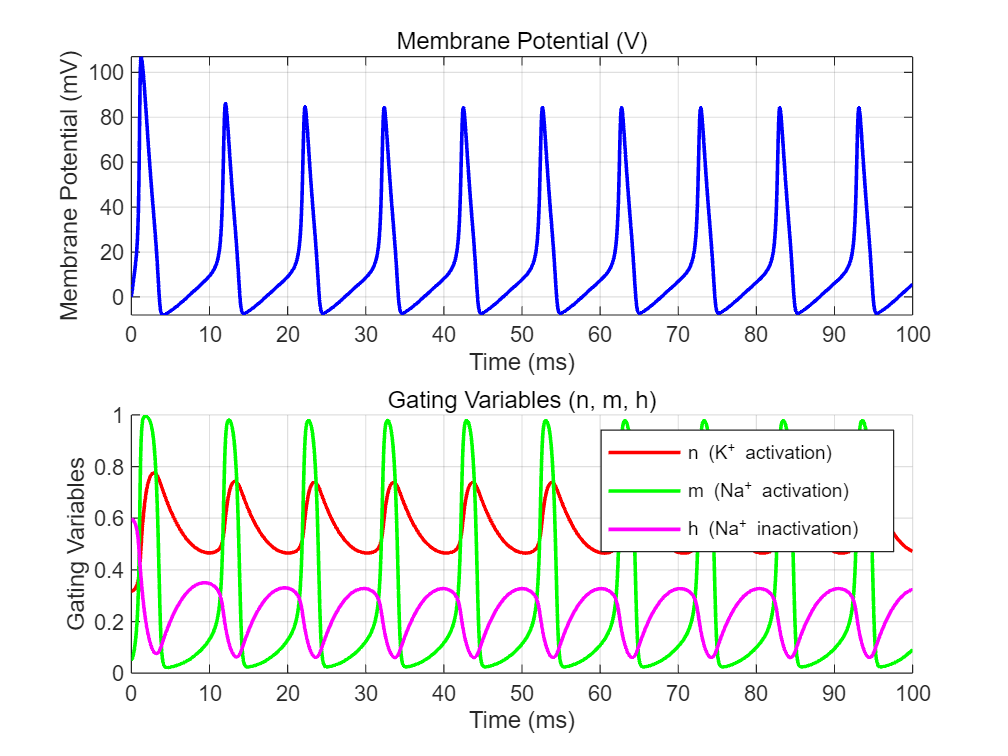

% Input current (uA/cm^2)
I = 30; % Constant input current

% Time span for simulation (ms)
tspan = [0 100]; % Simulate Time

% Initial conditions: V, n, m, h
V0 = 0.003620668807943; % Initial membrane potential (mV)
n0 = alpha_n(V0) / (alpha_n(V0) + beta_n(V0)); % Steady-state value of n
m0 = alpha_m(V0) / (alpha_m(V0) + beta_m(V0)); % Steady-state value of m
h0 = alpha_h(V0) / (alpha_h(V0) + beta_h(V0)); % Steady-state value of h
y0 = [V0; n0; m0; h0];

% Solve the ODE system using ode45
[t, y] = ode45(@(t, y) hodgkin_huxley(t, y, I, Cm, gK, gNa, gL, VK, VNa, VL), tspan, y0);

% Extract results
V = y(:, 1); % Membrane potential
n = y(:, 2); % Potassium activation gate
m = y(:, 3); % Sodium activation gate
h = y(:, 4); % Sodium inactivation gate

% Subplot 1: Membrane potential V
subplot(2, 1, 1);
plot(t, V, 'LineWidth', 1.5, 'Color', 'b');
% ylim([-30 30]) % If you are watching resting potential
xlabel('Time (ms)');
ylabel('Membrane Potential (mV)');
title('Membrane Potential (V)');
grid on;

% Subplot 2: All gating variables (n, m, h) in the same plot
subplot(2, 1, 2);
hold on;

% Plot potassium activation gate n
plot(t, n, 'LineWidth', 1.5, 'Color', 'r', 'DisplayName', 'n (K^+ activation)');

% Plot sodium activation gate m
plot(t, m, 'LineWidth', 1.5, 'Color', 'g', 'DisplayName', 'm (Na^+ activation)');

% Plot sodium inactivation gate h
plot(t, h, 'LineWidth', 1.5, 'Color', 'm', 'DisplayName', 'h (Na^+ inactivation)');

% Set axis limits and labels
ylim([0 1]); % 门控变量范围为 [0, 1]
xlabel('Time (ms)');
ylabel('Gating Variables');
title('Gating Variables (n, m, h)');
legend('Location', 'NorthEast'); % 添加图例以区分不同变量
grid on;
hold off; % 结束多条曲线绘制

# 数值求解静息膜电位

% 定义非线性方程：总离子电流 = 0
F = @(V) gK * (alpha_n(V)/(alpha_n(V)+beta_n(V)))^4 * (V - VK) + ...
         gNa * (alpha_m(V)/(alpha_m(V)+beta_m(V)))^3 .* ...
         (alpha_h(V)/(alpha_h(V)+beta_h(V))) * (V - VNa) + ...
         gL * (V - VL);

% 使用 fzero 求解 F(V) = 0
V_rest = fzero(F, -10); % 初始猜测值设为 -10 mV

% 计算稳态门控变量
n_rest = alpha_n(V_rest) / (alpha_n(V_rest) + beta_n(V_rest));
m_rest = alpha_m(V_rest) / (alpha_m(V_rest) + beta_m(V_rest));
h_rest = alpha_h(V_rest) / (alpha_h(V_rest) + beta_h(V_rest));

% 输出结果
fprintf('静息膜电位 V_rest = %.2f mV\n', V_rest);

静息膜电位 V_rest = 0.00 mV


fprintf('稳态门控变量: n=%.4f, m=%.4f, h=%.4f\n', n_rest, m_rest, h_rest);

稳态门控变量: n=0.3177, m=0.0530, h=0.5960


# 绘制 Gain Function

% Input current range (uA/cm^2)
I_values = 0:1:50; % 从0到50 μA/cm²，步长1

% Time span for simulation (ms)
tspan = [0 1000]; % 延长仿真时间至1000 ms
transient_time = 200; % 忽略前200 ms的瞬态

% Initial conditions (steady-state at resting potential)
V0 = 0.003620668807943; % Initial membrane potential (mV)
n0 = alpha_n(V0) / (alpha_n(V0) + beta_n(V0)); % Steady-state value of n
m0 = alpha_m(V0) / (alpha_m(V0) + beta_m(V0)); % Steady-state value of m
h0 = alpha_h(V0) / (alpha_h(V0) + beta_h(V0)); % Steady-state value of h
y0 = [V0; n0; m0; h0];

% Preallocate results
firing_rate = zeros(size(I_values));

% Loop over input currents
for idx = 1:length(I_values)
    I = I_values(idx);
    % Solve ODE
    [t, y] = ode45(@(t, y) hodgkin_huxley(t, y, I, Cm, gK, gNa, gL, VK, VNa, VL), tspan, y0);
    V = y(:, 1);
    
    % 忽略瞬态阶段
    valid_idx = t > transient_time;
    V_valid = V(valid_idx);
    t_valid = t(valid_idx);
    
    % 检测动作电位峰值（阈值设为4 mV）
    [pks, locs] = findpeaks(V_valid, 'MinPeakHeight', 4, 'MinPeakDistance', 5);
    num_spikes = length(pks);
    time_window = t_valid(end) - t_valid(1);
    firing_rate(idx) = num_spikes / (time_window / 1000); % 转换为Hz
end

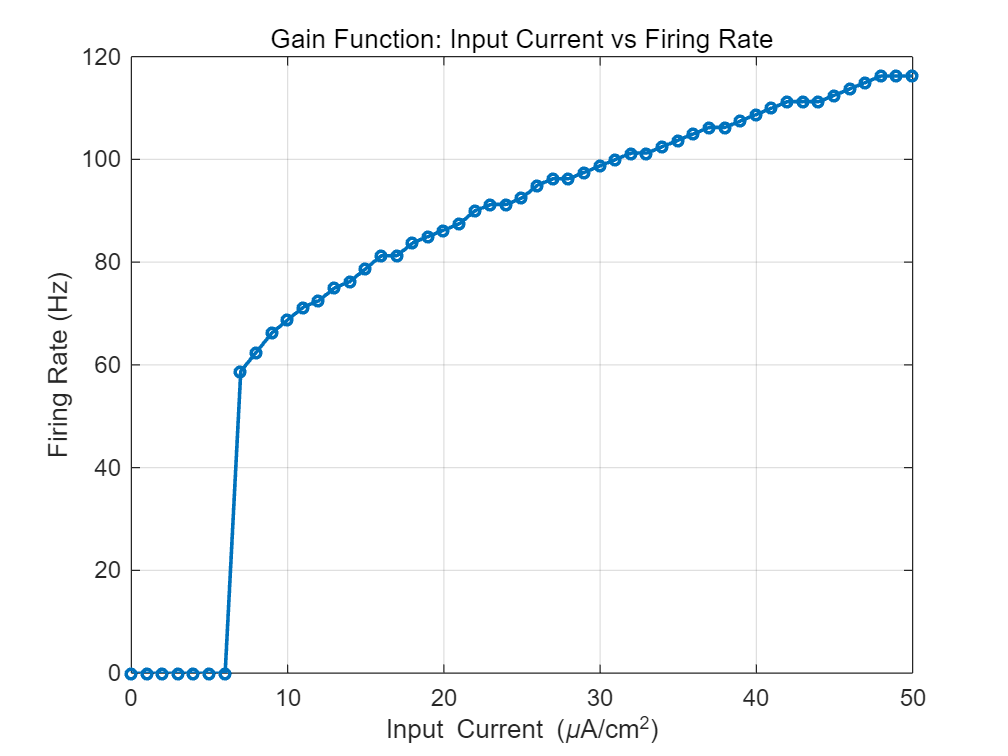


% Plot Gain Function
figure;
plot(I_values, firing_rate, '-o', 'MarkerSize', 4, 'LineWidth', 1.5);
xlabel('Input Current (\muA/cm^2)');
ylabel('Firing Rate (Hz)');
title('Gain Function: Input Current vs Firing Rate');
grid on;

# 模拟癫痫样神经元

增加模型中钠通道的密度为原来的两倍，模拟不输入电流的情况下，癫痫样神经元的过度放电

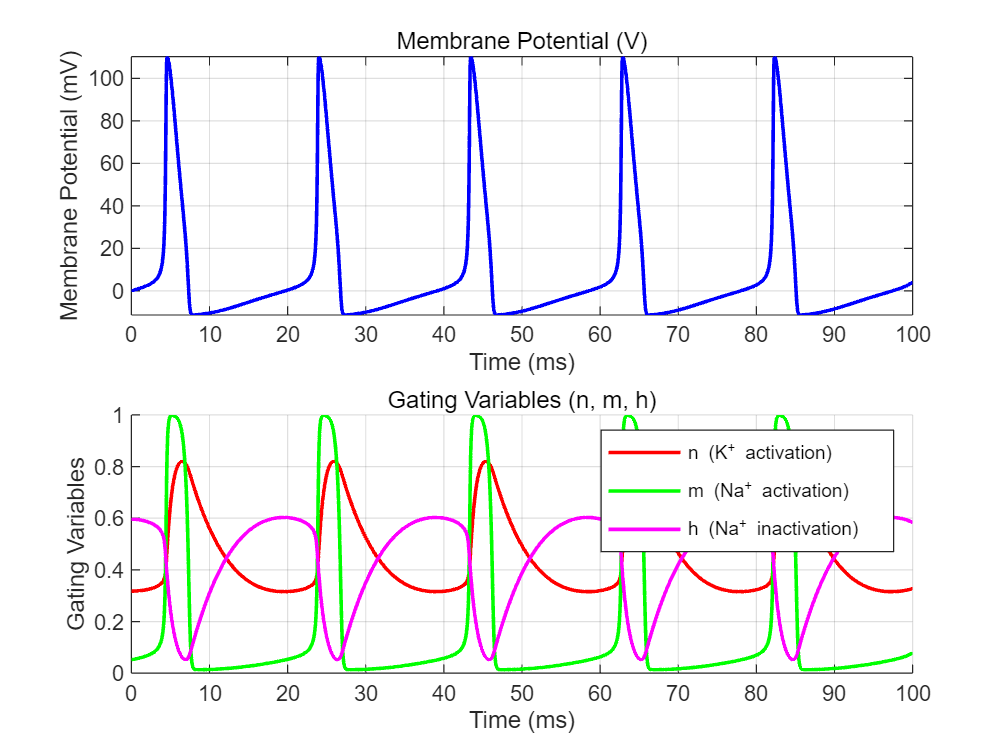

gNa = 240.0; % Sodium conductance doubled (original: 120)

% Input current (uA/cm^2)
I = 0; % Constant input current

% Time span for simulation (ms)
tspan = [0 100]; % Simulate Time

% Initial conditions: V, n, m, h
V0 = 0.003620668807943; % Initial membrane potential (mV)
n0 = alpha_n(V0) / (alpha_n(V0) + beta_n(V0)); % Steady-state value of n
m0 = alpha_m(V0) / (alpha_m(V0) + beta_m(V0)); % Steady-state value of m
h0 = alpha_h(V0) / (alpha_h(V0) + beta_h(V0)); % Steady-state value of h
y0 = [V0; n0; m0; h0];

% Solve the ODE system using ode45
[t, y] = ode45(@(t, y) hodgkin_huxley(t, y, I, Cm, gK, gNa, gL, VK, VNa, VL), tspan, y0);

% Extract results
V = y(:, 1); % Membrane potential
n = y(:, 2); % Potassium activation gate
m = y(:, 3); % Sodium activation gate
h = y(:, 4); % Sodium inactivation gate

% Subplot 1: Membrane potential V
subplot(2, 1, 1);
plot(t, V, 'LineWidth', 1.5, 'Color', 'b');
% ylim([-30 30]) % If you are watching resting potential
xlabel('Time (ms)');
ylabel('Membrane Potential (mV)');
title('Membrane Potential (V)');
grid on;

% Subplot 2: All gating variables (n, m, h) in the same plot
subplot(2, 1, 2);
hold on;

% Plot potassium activation gate n
plot(t, n, 'LineWidth', 1.5, 'Color', 'r', 'DisplayName', 'n (K^+ activation)');

% Plot sodium activation gate m
plot(t, m, 'LineWidth', 1.5, 'Color', 'g', 'DisplayName', 'm (Na^+ activation)');

% Plot sodium inactivation gate h
plot(t, h, 'LineWidth', 1.5, 'Color', 'm', 'DisplayName', 'h (Na^+ inactivation)');

% Set axis limits and labels
ylim([0 1]); % 门控变量范围为 [0, 1]
xlabel('Time (ms)');
ylabel('Gating Variables');
title('Gating Variables (n, m, h)');
legend('Location', 'NorthEast'); % 添加图例以区分不同变量
grid on;
hold off; % 结束多条曲线绘制

# LIF Model

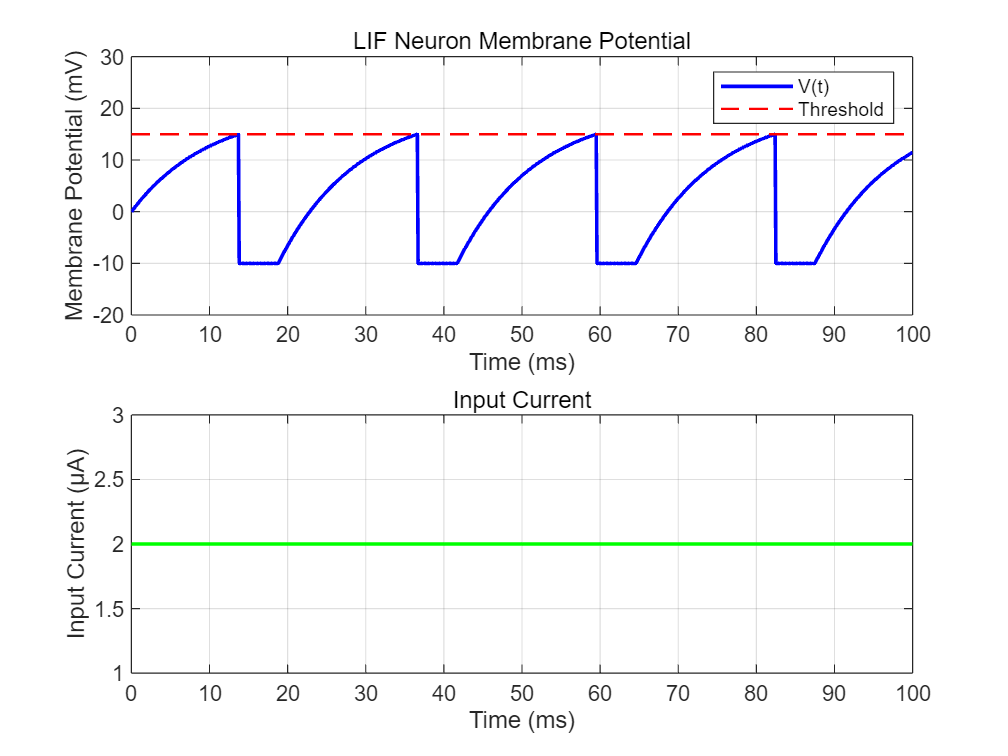

% 参数设置
tau_m = 10;          % 膜时间常数 (ms)
V_rest = 0;        % 静息电位 (mV)
V_threshold = 15;   % 阈值电位 (mV)
V_reset = -10;       % 重置电位 (mV)
Rm = 10;              % 膜电阻 (M Omega)
I = 2;               % 输入电流 (uA)
t_refractory = 5;    % 绝对不应期 (ms)

% 仿真参数
t_total = 100;       % 总仿真时间 (ms)
dt = 0.1;            % 时间步长 (ms)
tspan = 0:dt:t_total;

% 初始化变量
V = zeros(size(tspan));  % 膜电位
V(1) = V_rest;           % 初始膜电位为静息电位
spike_times = [];        % 记录发放时间
refractory_counter = 0;  % 不应期计数器

% 数值积分（显式欧拉法）
for i = 2:length(tspan)
    % 不应期内：不更新膜电位
    if refractory_counter > 0
        V(i) = V_reset;
        refractory_counter = refractory_counter - 1;
        continue;
    end
    
    % 更新膜电位（LIF微分方程：tau_m dV/dt = -(V - V_rest) + Rm*I）
    dV = (-(V(i-1) - V_rest) + Rm*I) / tau_m * dt;
    V(i) = V(i-1) + dV;
    
    % 触发动作电位
    if V(i) >= V_threshold
        V(i) = V_reset;  % 重置膜电位
        spike_times = [spike_times, tspan(i)];  % 记录发放时间
        refractory_counter = round(t_refractory / dt);  % 设置不应期
    end
end

% 可视化结果
figure;
subplot(2,1,1);
plot(tspan, V, 'b', 'LineWidth', 1.5);
hold on;
plot([tspan(1), tspan(end)], [V_threshold, V_threshold], 'r--', 'LineWidth', 1);
ylim([-20, 30])
xlabel('Time (ms)');
ylabel('Membrane Potential (mV)');
title('LIF Neuron Membrane Potential');
legend('V(t)', 'Threshold');
grid on;

subplot(2,1,2);
plot(tspan, I*ones(size(tspan)), 'g', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('Input Current (μA)');
title('Input Current');
grid on;